%https://drive.google.com/open?id=10GeqpN-dwusa93hQUYOxrH0FnkiIc2a6
Temlate_matcher=vision.TemplateMatcher('OutputValue', ...
                'Best match location', 'BestMatchNeighborhoodOutputPort', true);

I = rgb2gray(imread('C:\Users\bengo\Downloads\Photos\01.jpg'));
T = rgb2gray(imread('C:\Users\bengo\Downloads\Photos\03.jpg'));

location = step(Temlate_matcher,I,T);
[Location1, NVALS, NVALID] = step(Temlate_matcher,I,T);
val = min(NVALS(:));
I = imresize(I, 0.5)

I = 720×540 uint8 matrix
   220   220   221   221   222   222   222   221   219   219   220   220   219   219   219   218   218   217   217   216   214   214   212   212   212   212   211   211   211   211   211   211   212   213   213   213   212   212   213   213   213   213   213   214   215   216   217   217   218   218
   221   221   220   220   222   222   221   221   220   220   219   219   219   219   218   218   218   217   216   215   215   215   213   213   213   212   212   211   211   211   211   211   211   211   212   212   212   212   213   213   213   213   213   214   214   215   216   217   217   217
   220   220   220   221   222   222   221   221   221   220   219   218   218   218   218   217   217   217   215   215   215   215   213   213   213   212   212   211   211   211   211   211   210   210   211   211   211   211   212   212   212   213   213   213   214   214   215   214   215   216
   219   220   220   221   222   221   221   221   221   220   219   218

T = imresize(T, 0.5)

T = 720×540 uint8 matrix
    54    64    81    76    72    70    70    74    74    76    77    73    70    71    72    72    76    72    66    61    63    71    63    70    68    68    68    68    74    82    93    96    93    84    72    73    86    93   100   132   182   201   205   207   205   204   203   203   201   200
    60    72    75    74    75    70    73    76    78    77    74    71    72    74    73    73    75    74    69    65    62    66    65    70    69    70    68    70    76    84    94    97    95    88    73    73    78    84    88   107   157   187   202   205   204   204   204   202   200   201
    62    64    68    71    73    73    72    75    80    78    76    73    73    74    75    75    74    75    68    69    63    65    68    73    71    72    68    70    74    81    92    97    95    88    79    76    75    78    77    82   120   163   195   203   204   204   203   202   200   200
    66    68    64    67    70    72    76    76    76    75    75    74

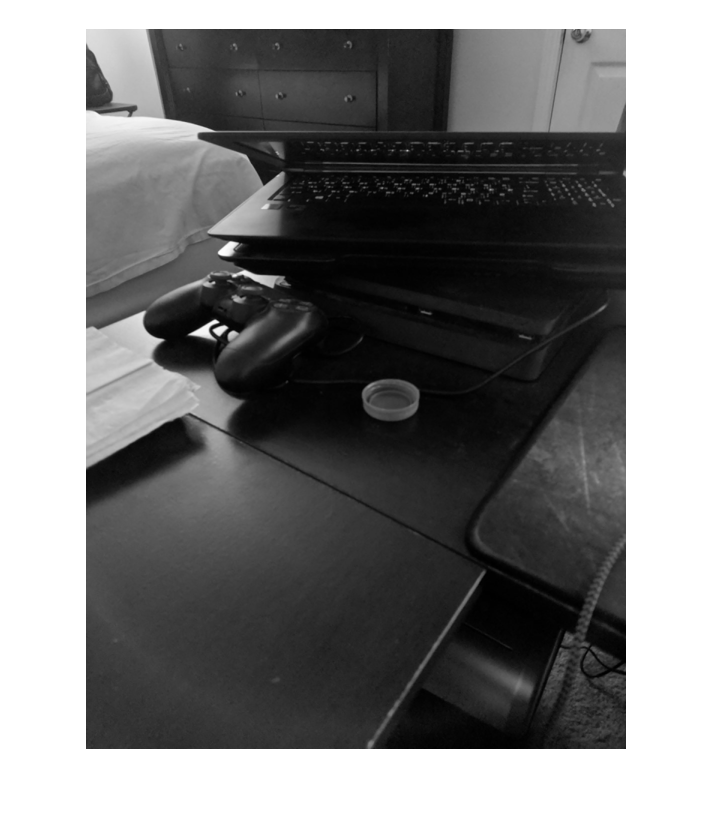

imshow(I)

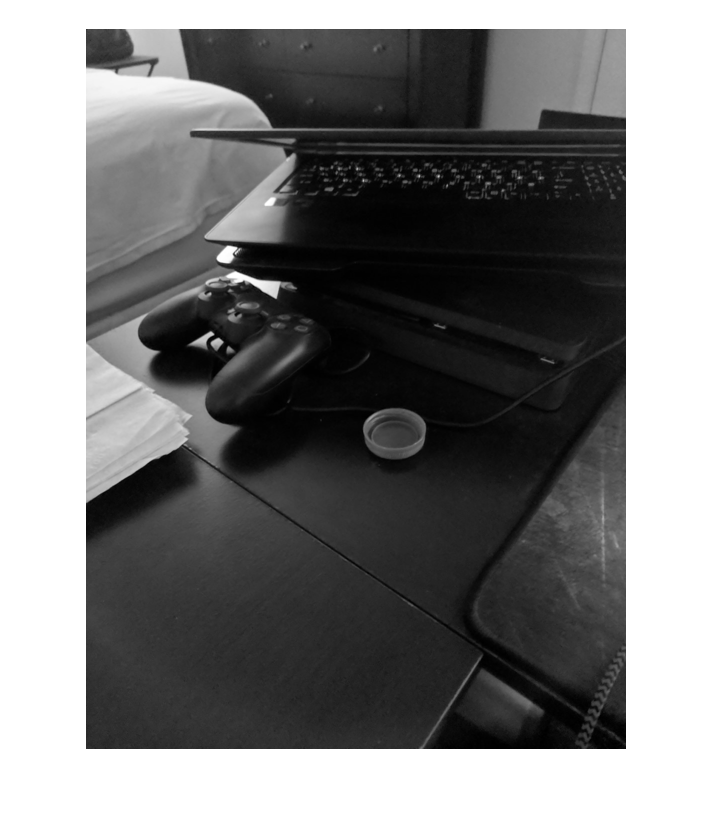

imshow(T)